# Assignment 3

Mapping Example

#### S- Domain poles

% s = 0
% s = -3
% s = +0.1
% s = -3j
% s = +3j
s = [0 -3 0.1 -3j 3j];

#### Generate z-poles (Lab 6)

- z = e^(s*T)

- s = (1/T) * ln(z)

T = 1;                  % Sampling Time
z = exp(s*T);           % Z- Mapping

#### Plot S-Domain poles

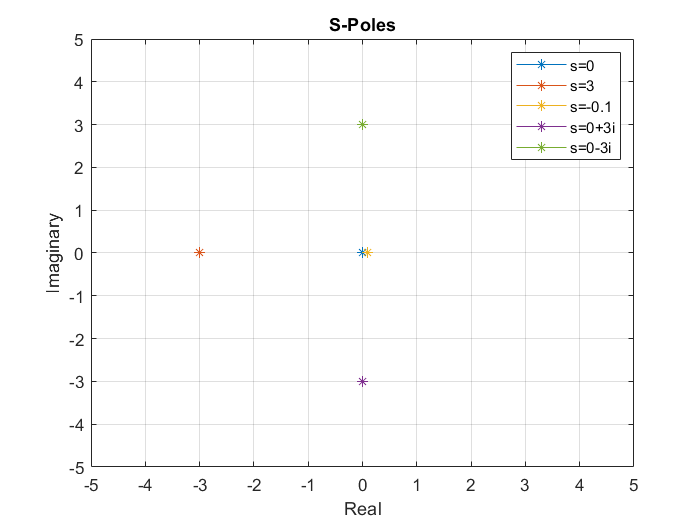

% Allocate legends (1 x num of poles)
l = strings(1,length(s));
% Create figure
h1 = figure('Name','S-Domain');
% loop to plot each point
% so each point has a color
for i = 1 : length(s)
    plot(real(s(i)),imag(s(i)),'Marker',"*")
    hold on
    % generate legend for each point (s=-pole)
    l(i) = "s=" + -s(i);
end
% widen axes limits
xlim([-5 5]), ylim([-5 5])
grid on
xlabel("Real"), ylabel("Imaginary")
title("S-Poles")
legend(l)

#### Plot Z-Domain poles

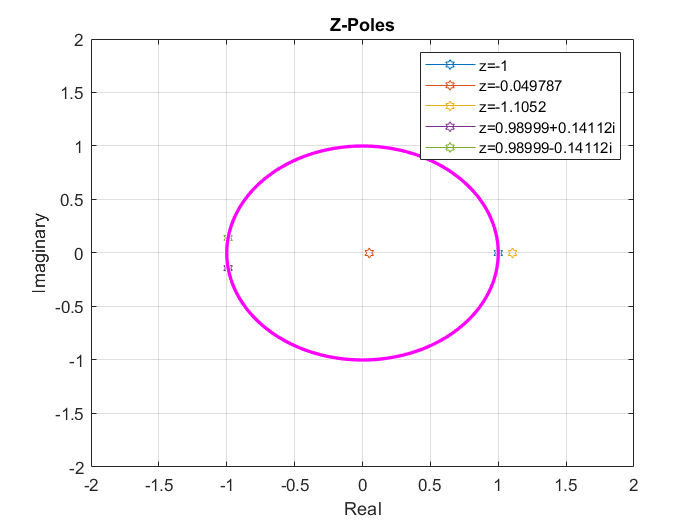

% Allocate legends (1 x num of poles)
l = strings(1,length(z));
% Create figure
h2 = figure('Name','Z-Domain');
% loop to plot each point
% so each point has a color
for i = 1 : length(z)
    plot(real(z(i)),imag(z(i)),'Marker',"hexagram","MarkerSize",6)
    hold on
    % generate legend for each point (z=-pole)
    l(i) = "z=" + -z(i);
end
% widen axes limits
xlim([-2 2]), ylim([-2 2])
grid on
xlabel("Real"), ylabel("Imaginary")
title("Z-Poles")
legend(l)
viscircles([0 0],1,'color','magenta');